# Landscape

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
f(X) = \min_{Q} f(X,Q) = f\bigg(\frac{1}{k}\sum_j^k Y_jQ_j, Q\bigg) =f(\chi(Q),Q)
\\
\nabla f(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), \big(Y_j^\top(Y_jQ_j-X)\big)_j\bigg)
\\
\nabla^2 f(X,Q)[U,V] = \nabla f(U,V)$$


## Slices

seed=randi(100,1) %38

seed = 10

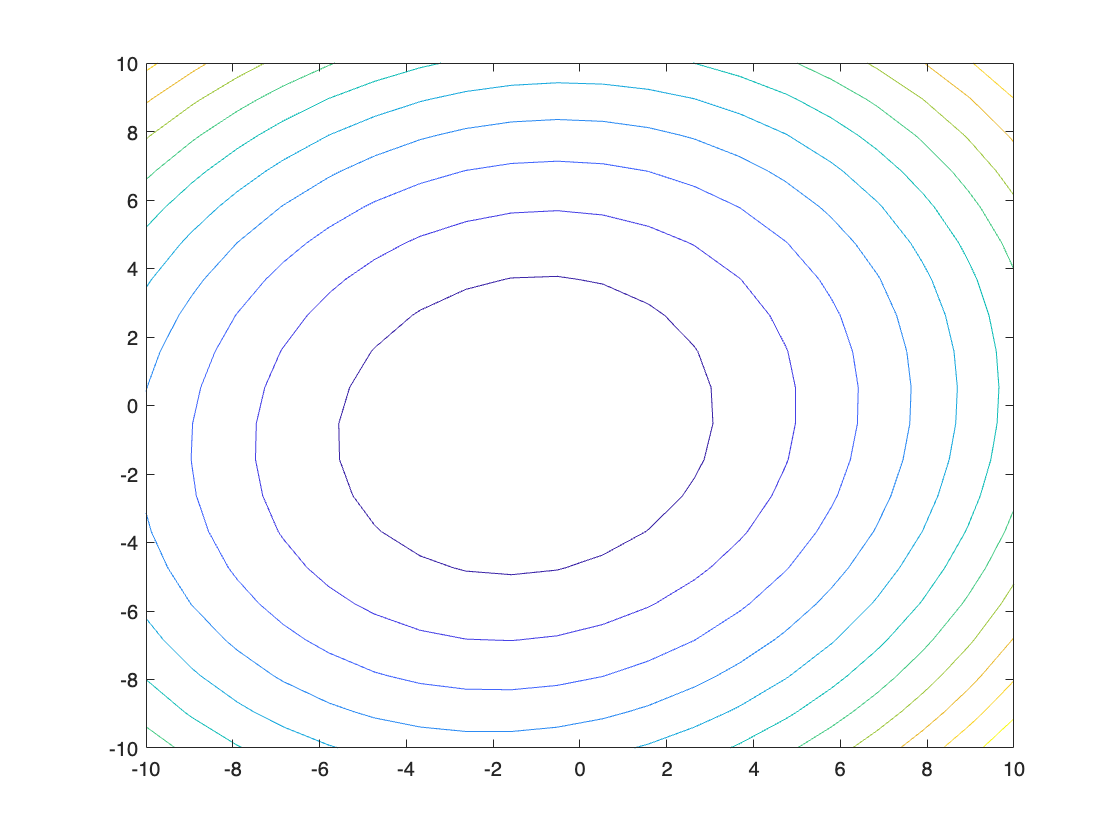

rng(seed)
n=32; % data dimension
r=2; % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B
k=100; % number of matrices
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

t = linspace(-10,10,20);
costs = surfprofile(prob,[],[],[],t,t);
contour(t, t, costs.')

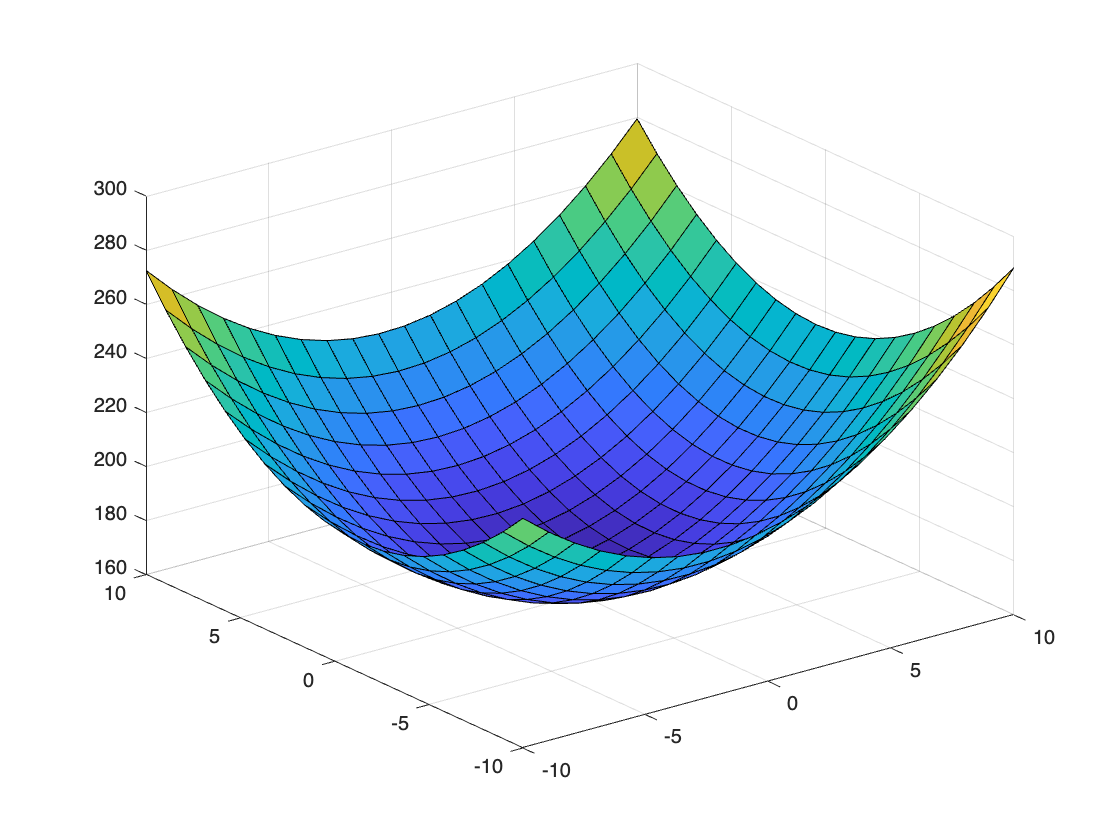

surf(t, t, costs.')

## Dependance to the initialization

clear
n=32; % data dimension
rr=round(logspace(0,log10(n),7)); % size of factorization Y of data A (chose <8 if n=32)
pp=rr; % size of factorization X of barycenter B
k=100; % number of matrices
Nrepeat=10;

mybar = waitbar(0,"Initialization");
Brelative_std = NaN(length(rr));
niter = NaN(length(rr));
options.verbosity=0;

for jr=1:length(rr)
    r=rr(jr);
    for jp=jr:length(pp)
        p=pp(jp);

        A = data(n,k,r);
        prob = nonconvex_problem(A,r,p);
        X = zeros(n,p,Nrepeat);
        niter(jr,jp)=0;

        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",r,p,n,j,Nrepeat))
            [x,~,info] = trustregions(prob,[],options);
            X(:,:,j) = x.X;
            niter(jr,jp) = niter(jr,jp) + info(end).iter;
        end
        
        niter(jr,jp) = niter(jr,jp) / Nrepeat;
        BB = pagemtimes(X, multitransp(X));
        Bmean = sum(BB,3)/Nrepeat;
        Bstd = norm(Bmean-BB,"fro")/(Nrepeat-1);
        Brelative_std(jr,jp) = Bstd/norm(Bmean,"fro");
    end
end
close(mybar)
%save("data/consitency_rp.mat","Brelative_std","niter")

load("data/consitency_rp.mat")
heatmap(pp,rr,Brelative_std)

Unrecognized function or variable
'pp'.

title(sprintf("Relative STD \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
%exportgraphics(gcf,"graphics/landscape_relative_std.pdf")
heatmap(pp,rr,niter)
title(sprintf("Number of iterations \n %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
%exportgraphics(gcf,"graphics/landscape_iterations.pdf")

## Convergence to cvx solution

Whishart Z*Z' model, with true barycenter by CVX

clear
n=10; % data dimension
rr=1:1:5; % size of factorization Y of data A (chose <8 if n=32)
pp=rr; % size of factorization X of barycenter B
k=10; % number of matrices
Nrepeat=5;

mybar = waitbar(0,"Initialization");
Berr = NaN(length(rr),length(pp),Nrepeat);
costerr = NaN(length(rr),length(pp),Nrepeat);
options.verbosity=0;

for jr=1:length(rr)
    for jp=1:length(pp)
        if pp(jp) < rr(jr) % invalid (must r <= p)
            continue
        end
        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",rr(jr),pp(jp),n,j,Nrepeat))

            A = data(n,k,rr(jr)); % data
            [Bcvx,cost_cvx,info_cvx] = cvx_solve(A); % compute true barycenter by cvx
            prob = nonconvex_problem(A,rr(jr),pp(jp)); % nonconvex problem
            [x,cost,info] = trustregions(prob,[],options); % solve
            B = x.X * x.X';
            Berr(jr,jp,j) = norm(Btrue-B,"fro")/norm(Btrue,"fro");
            costerr(jr,jp,j) = cost - prob.variance(Btrue);
            niter(jr,jp,j) = info(end).iter;
        end
    end
end

close(mybar)
%save("data/convergence2cvx.mat")

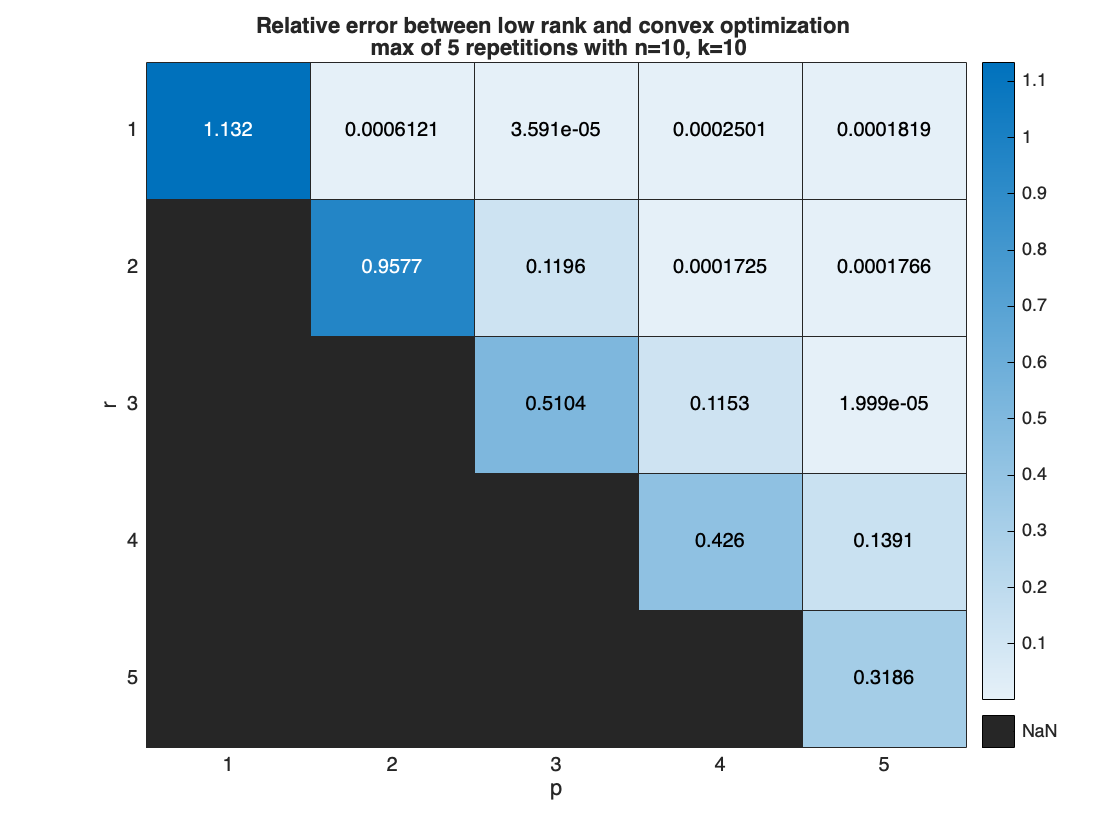

load("data/convergence2cvx.mat")
heatmap(pp,rr,max(Berr,[],3))
title(sprintf("Relative error between low rank and convex optimization \n max of %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
exportgraphics(gcf,"graphics/convergence2cvx.pdf")

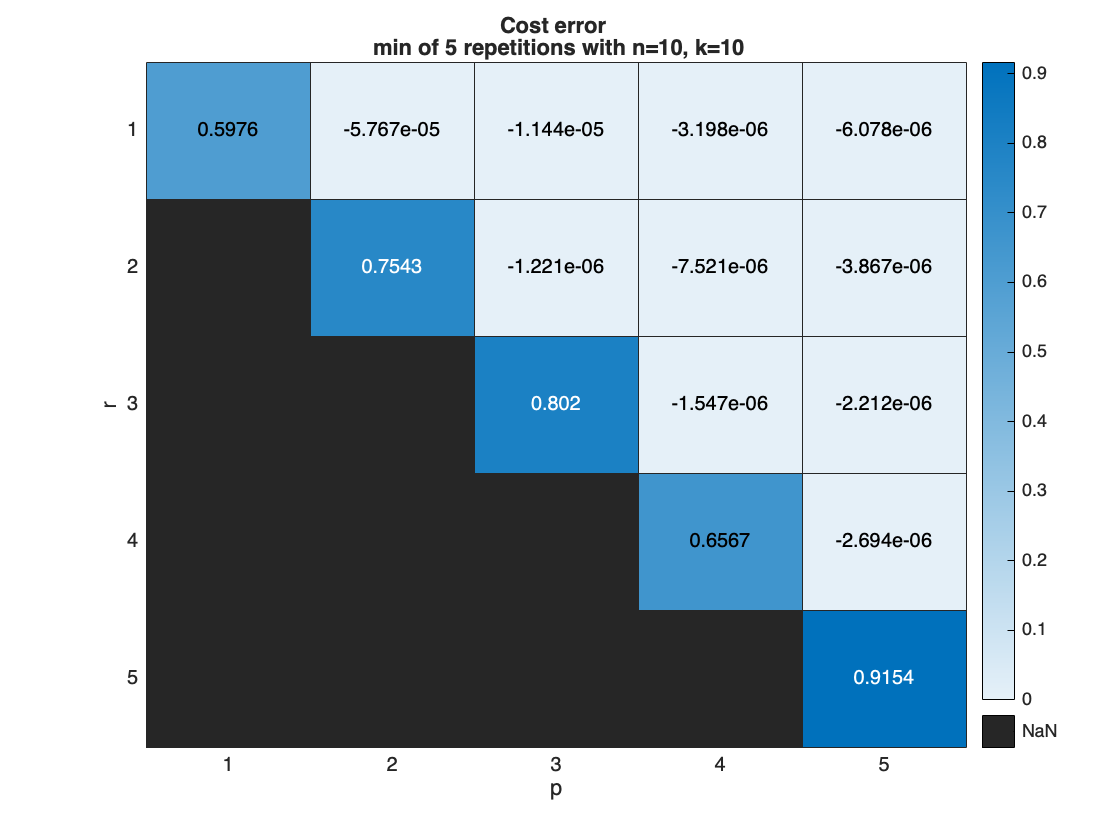

heatmap(pp,rr,min(costerr,[],3))
title(sprintf("Cost error \n min of %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
exportgraphics(gcf,"graphics/convergence2cvx_costerr.pdf")

## Convergence to true barycenter

CBC Model

clear
n=100; % data dimension
rr=1:1:5; % size of factorization Y of data A (chose <8 if n=32)
pp=rr; % size of factorization X of barycenter B
k=10; % number of matrices
Nrepeat=10;

mybar = waitbar(0,"Initialization");
Berr = NaN(length(rr),length(pp),Nrepeat);
costerr = NaN(length(rr),length(pp),Nrepeat);
options.verbosity=0;

for jr=1:length(rr)
    for jp=1:length(pp)
        if pp(jp) < rr(jr) % invalid
            continue
        end
        for j=1:Nrepeat
            waitbar((jr+(jp+j/Nrepeat)/length(pp))/length(rr), mybar,...
                sprintf("(r,p)/n=(%d,%d)/%d \n iteration %d/%d",rr(jr),pp(jp),n,j,Nrepeat))

            Btrue = data(n,1,rr(jr)); % arbitrary target barycenter
            A = data_scaled(Btrue,k,"exact"); % data
            prob = nonconvex_problem(A,rr(jr),pp(jp)); % problem
            [x,cost,info] = trustregions(prob,[],options); % solve
            B = x.X * x.X';
            Berr(jr,jp,j) = norm(Btrue-B,"fro")/norm(Btrue,"fro");
            costerr(jr,jp,j) = cost - cost_variance(A,Btrue);
            niter(jr,jp,j) = info(end).iter;
        end
    end
end
close(mybar)
%save("data/convergence2Btrue.mat")

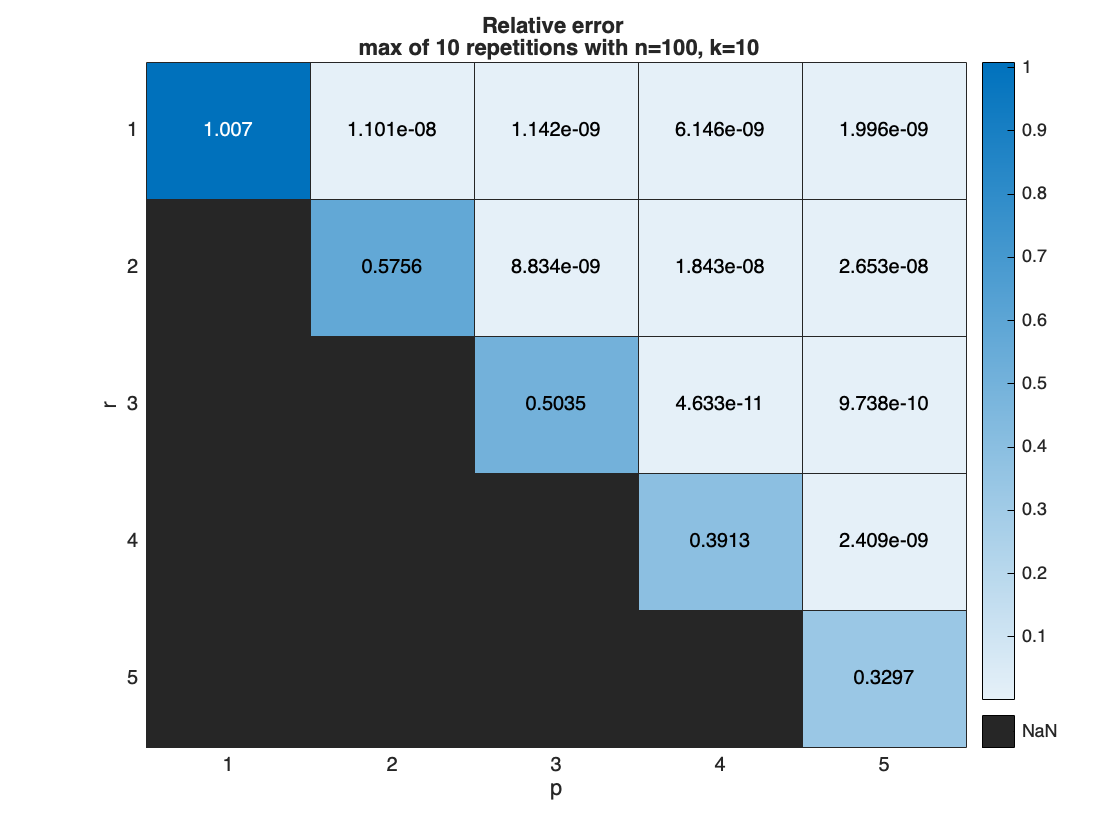

load("data/convergence2Btrue.mat")
heatmap(pp,rr,max(Berr,[],3))
title(sprintf("Relative error \n max of %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
exportgraphics(gcf,"graphics/convergence2Btrue_Berr.pdf")

disp([median(Berr(1,1,:)), median(Berr(2,2,:))])

    0.9663    0.5632



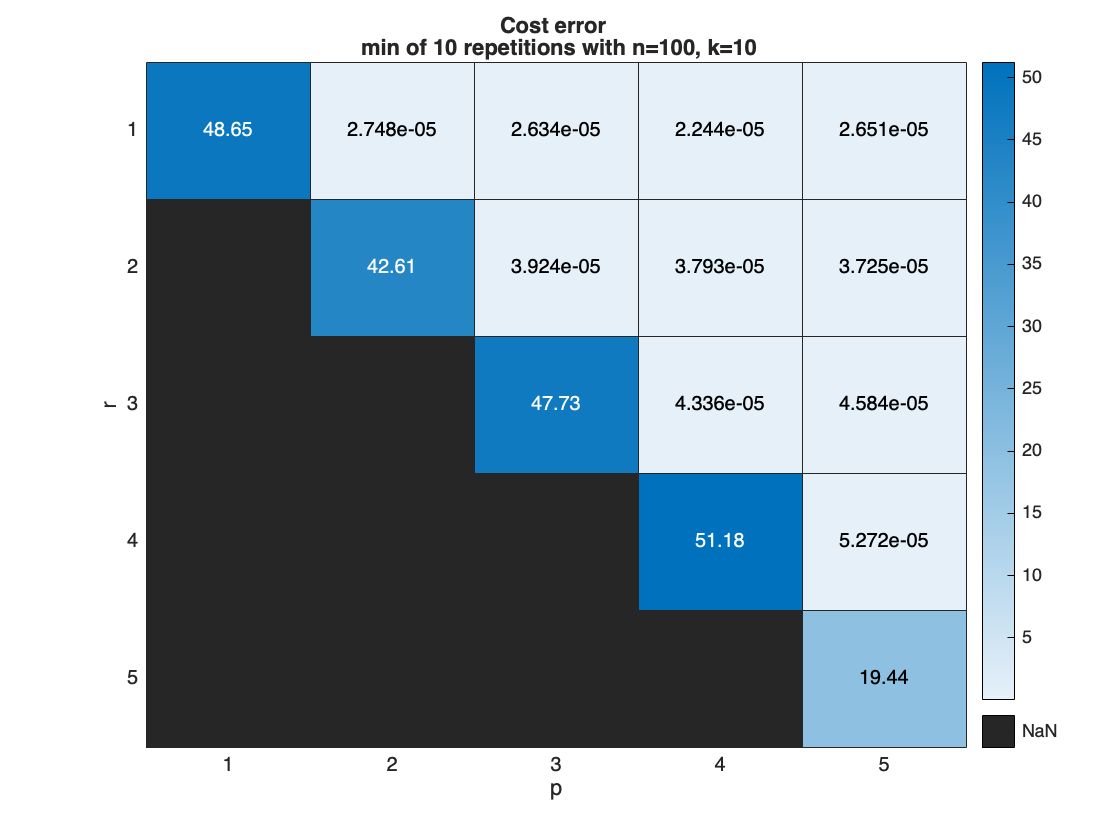

heatmap(pp,rr,min(costerr,[],3))
title(sprintf("Cost error \n min of %d repetitions with n=%d, k=%d",Nrepeat,n,k))
xlabel("p")
ylabel("r")
exportgraphics(gcf,"graphics/convergence2Btrue_costerr.pdf")

proba = 0.5^k % probability for orthogonal matrices initialization of being in the right connected component.

proba = 9.7656e-04

sum(Berr(5,5,:)<1e-3)

ans = 0

## Rank of solutions

clear
n=5; % data dimension
kk=2:2:10; % number of matrices
rr=1:2:n;
Nrepeat=3;
eigenvalues= zeros(length(kk),length(rr),n,Nrepeat);
for jk=1:length(kk)
    k=kk(jk)
    for jr=1:length(rr)
        r=rr(jr);
        Btrue=10*data(n,1,r);
        for j=1:Nrepeat
            %[k,r,j]
            A = data_scaled(Btrue,k,"exact");
            [B,Bcost,info] = cvx_solve(A);
            eigenvalues(jk,jr,:,j)=abs(eig(B));
        end
    end
end

k = 2

k = 4

k = 6

k = 8

k = 10

%save("data/rank.mat","eigenvalues")

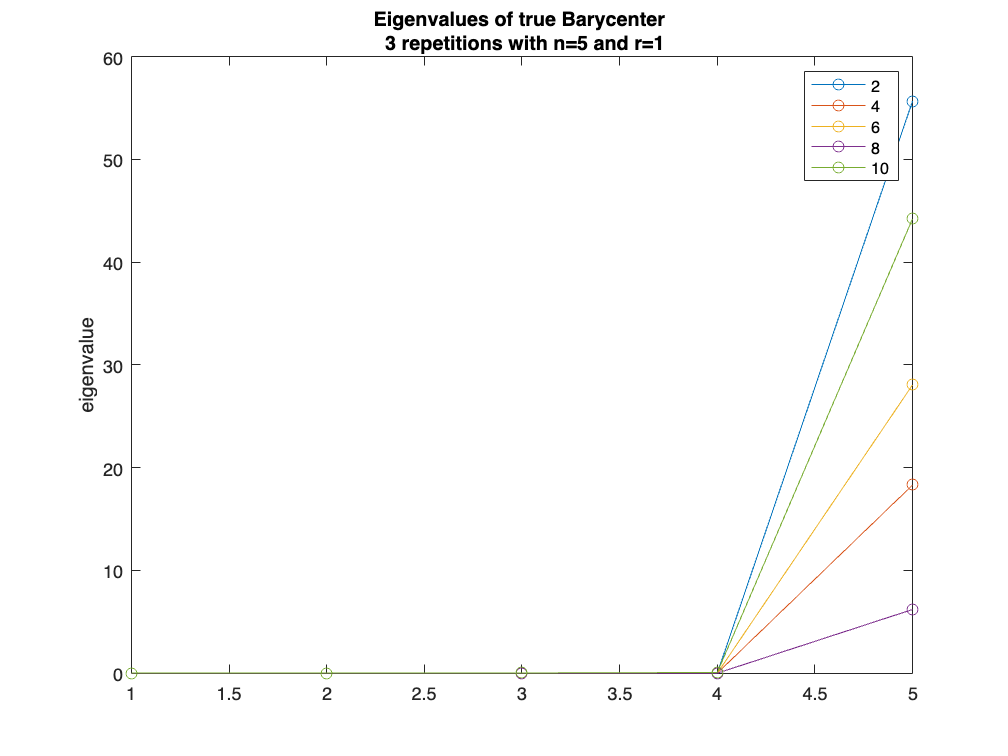

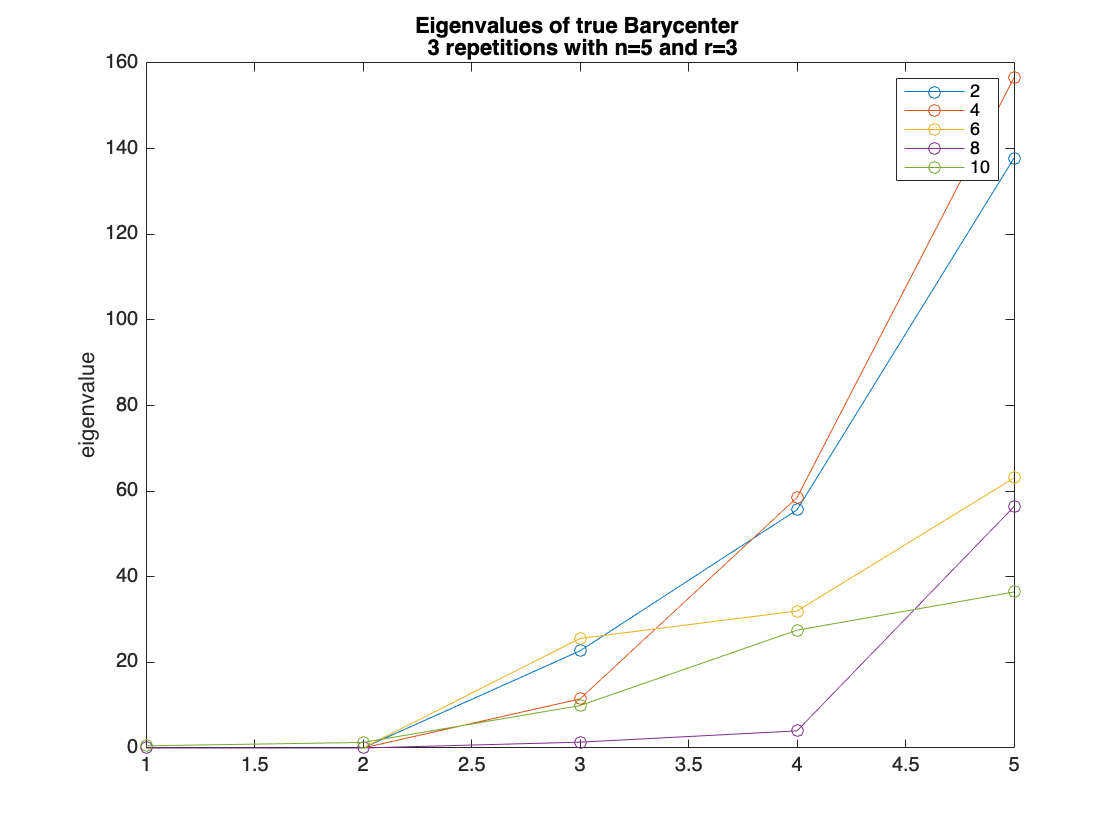

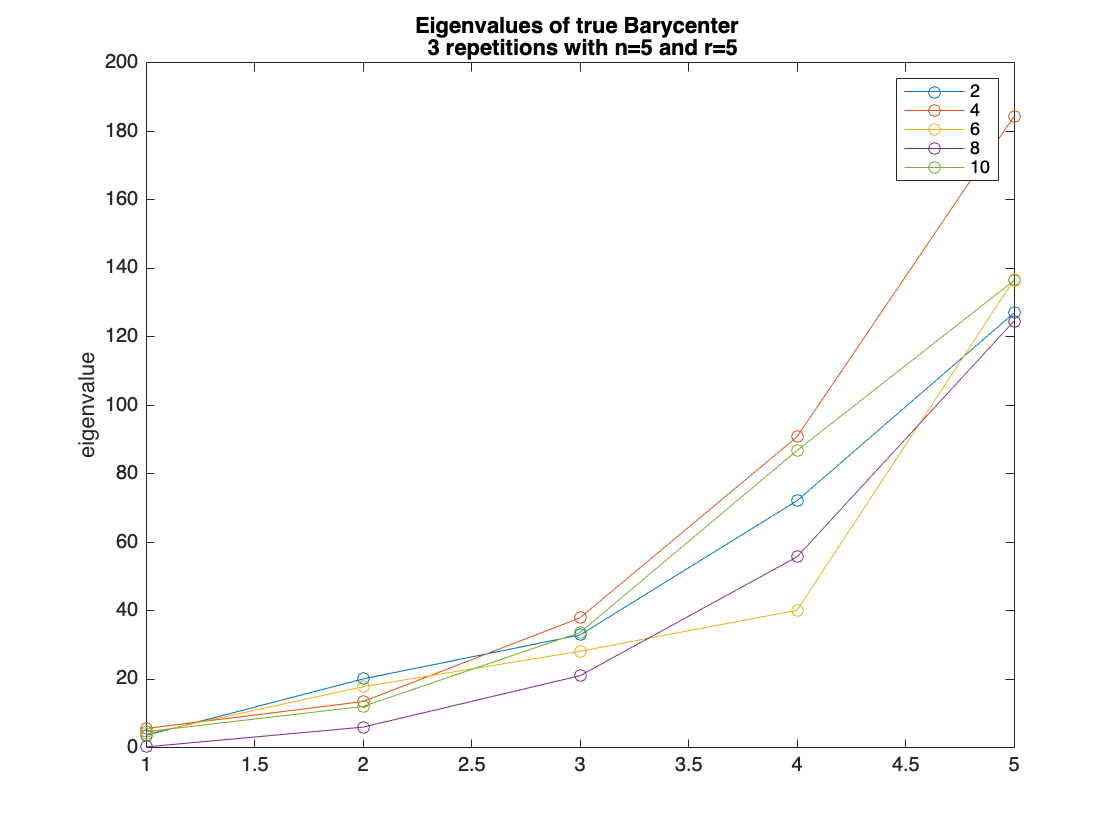

%load("data/rank.mat")
for jr=1:length(rr)
    eig_mean = mean(eigenvalues(:,jr,:,:),4);
    figure()
    plot(squeeze(eig_mean)',"o-")
    title(sprintf("Eigenvalues of true Barycenter \n %d repetitions with n=%d and r=%d",Nrepeat,n,rr(jr)))
    ylabel("eigenvalue")
    legend(string(kk))
    %exportgraphics(gcf,sprintf("graphics/rank_r%d.pdf",rr(jr)))
end

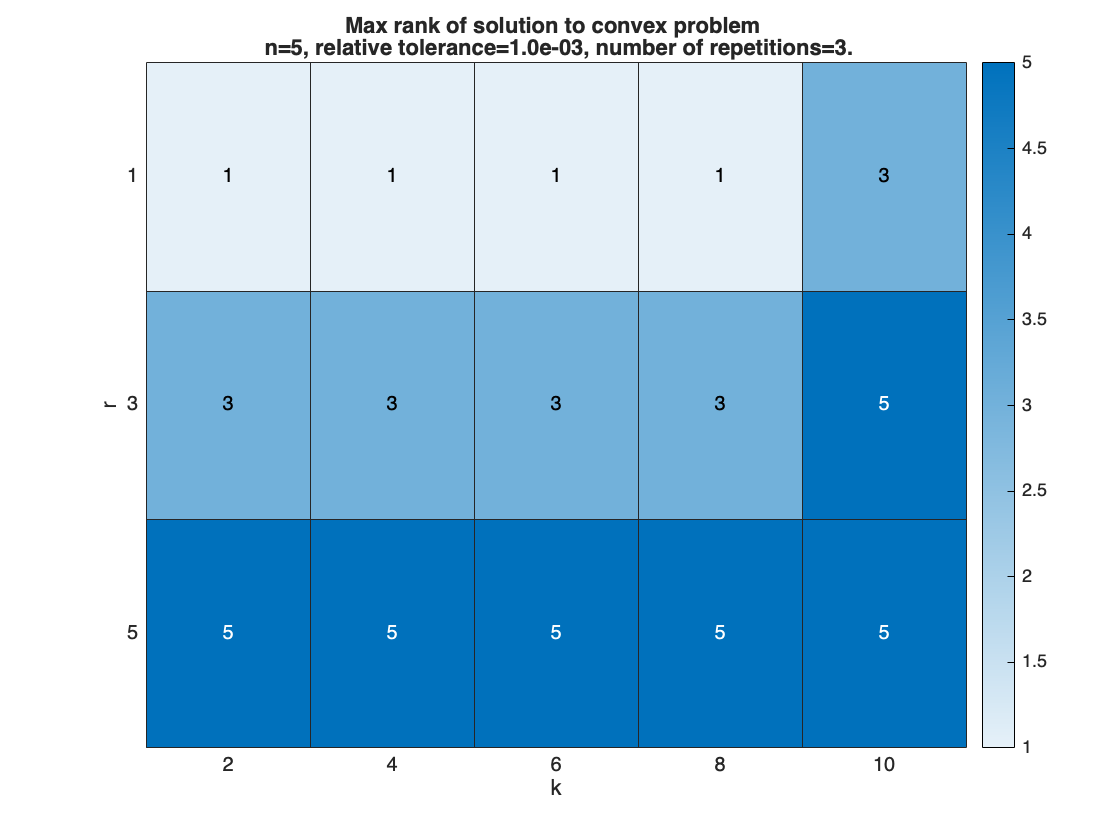

%load("data/rank.mat")
relat_tol=1e-3;
ranks = sum(eigenvalues > (relat_tol * eigenvalues(:,:,end,:)),3);
heatmap(kk,rr,max(ranks,[],4)')
xlabel("k")
ylabel("r")
title(sprintf("Max rank of solution to convex problem \n n=%d, relative tolerance=%.1e, number of repetitions=%d.",n,relat_tol,Nrepeat))

%exportgraphics(gcf,"graphics/ranks_rp.pdf")